# 使用 MATLAB 制作参与者动画

此示例展示了如何使用 `sim3d.World` 对象在虚幻引擎® 和 MATLAB® 之间建立协同仿真框架。`sim3d.World` 对象可以在每个仿真步骤中使用输出和更新函数向虚幻引擎发送和接收有关 `sim3d.Actor` 对象的数据。在虚幻引擎进行仿真之前，MATLAB 会调用输出函数。然后，虚幻引擎在每个时间步执行并在更新函数中发送回数据。

## 在世界场景中创建参与者

使用与虚幻引擎建立通信的函数创建世界场景。

world = sim3d.World('Output', @outputImpl, 'Update', @updateImpl);

实例化一个名为 Box1 的盒子参与者对象。将对象添加到世界场景中。

box1 = sim3d.Actor('ActorName', 'Box1', 'Mobility', sim3d.utils.MobilityTypes.Movable);
box1.createShape('box', [0.25 0.25 0.25]);
box1.Color = [1, 0, 1];
world.add(box1);

## 将相机添加到世界场景

使用 `sim3d.sensors.IdealCamera` 对象在虚幻引擎中捕获图像并将图像返回到 MATLAB。

camera1 = sim3d.sensors.IdealCamera("ActorName","Camera1", "ImageSize", [768, 1024], "HorizontalFieldOfView", 60);
camera1.Translation = [-3, 0, 2];
world.add(camera1);

## 设置查看器窗口视角

如果不创建视口，则视点设置为 0, 0 ,0，并且可以使用方向键和指针在三维仿真查看器窗口中导航。

对于本示例，使用该 `createViewport` 函数创建一个带有单个字段 Main 的视口，其中包含一个 `sim3d.sensors.MainCamera` 对象。

viewport = createViewport(world);
viewport.Translation = [-3, 0, 0.5];

## 运行动画

运行仿真集 2 秒，采样时间为 0.01 秒。Camera1 来的图像显示在 MATLAB 中。

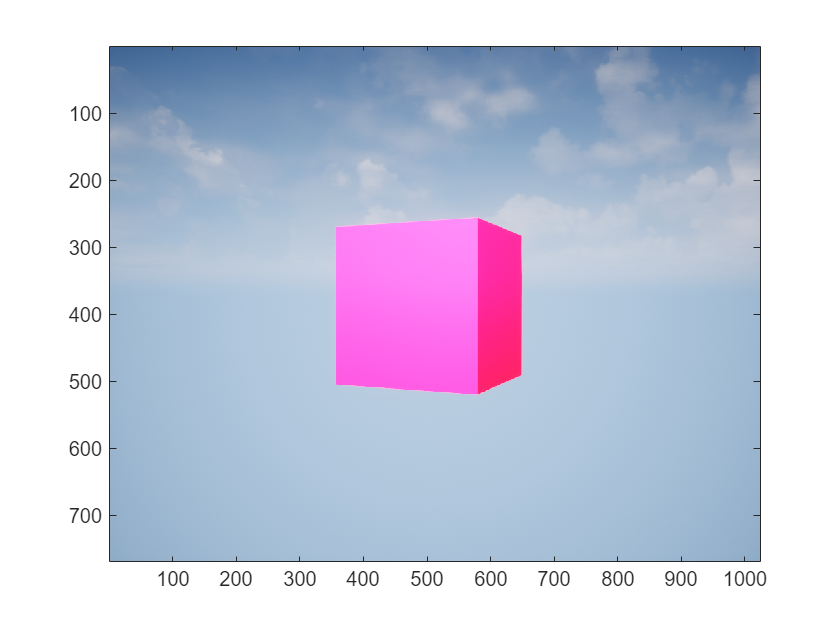

run(world,0.01,2)

## 删除世界

删除世界对象。

world.delete();

# 发送盒式参与者输出的函数

使用输出函数在每个仿真步骤发送数据。outputImpl 函数将有关参与者对象 Box1 的数据发送到虚幻引擎。

function outputImpl(world)
% Sets the actor outputs (e.g. a vehicle position to follow a path)
world.Actors.Box1.Translation(3) = world.Actors.Box1.Translation(3) + 0.01;
world.Actors.Box1.Rotation(3) = world.Actors.Box1.Rotation(3) + 0.01;
world.Actors.Box1.Scale = world.Actors.Box1.Scale + [0.01, 0.01, 0.01];
world.Actors.Box1.Color = world.Actors.Box1.Color + [0.01, 0, 0];
end

# 读取相机更新的函数

使用更新函数在每个仿真步骤读取数据。`updateImpl` 函数从虚幻引擎中的 `Camera1` 读取数据图像数据。

function updateImpl(world)
% Implements a control algorithm and updates the actor states (e.g. read a
% sensor and calculate a new vehicle position)
sceneImage = world.Actors.Camera1.read();
image(sceneImage);
end